clc; close all; clear all;

y_1_name = "y1.wav";
y_2_name = "y2.wav";
s_1_name = "Doimo_Ostan_s1_hat.wav";
s_2_name = "Doimo_Ostan_s2_hat.wav";
s_3_name = "Doimo_Ostan_s3_hat.wav";
% reference signal names

s_1_ref_name = "s1.wav"; 
s_2_ref_name = "s2.wav"; 
s_3_ref_name = "s3.wav"; 


if not(isfolder("audioOutputs"))
    mkdir("audioOutputs")
end

if not(isfolder("plots"))
    mkdir("plots")
end

addpath('audioInputs')
addpath('audioOutputs')
addpath('plots')

[y_1_t,y_1_Fs] = audioread(y_1_name);
[y_2_t,y_2_Fs] = audioread(y_2_name);
[s_1_ref_t,s_1_ref_Fs] = audioread(s_1_ref_name);
[s_2_ref_t,s_2_ref_Fs] = audioread(s_2_ref_name);
[s_3_ref_t,s_3_ref_Fs] = audioread(s_3_ref_name);
y_1_t_len = length(y_1_t);
y_2_t_len = length(y_2_t);

M=512

M = 512

MM = 2*M

MM = 1024

R=M/2

R = 256

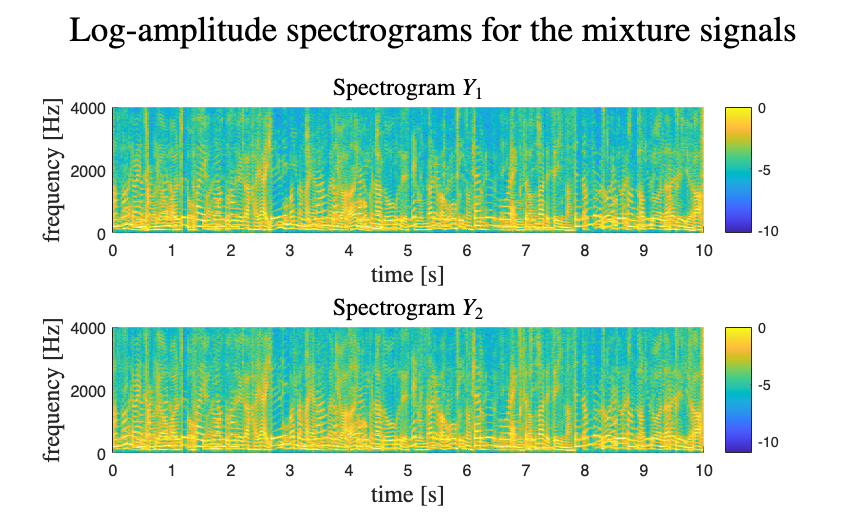

winType = "hamming";

y_1_st_w = mystft(y_1_t,winType,M,R,0);
y_2_st_w = mystft(y_2_t,winType,M,R,0);

y_11_st_w = y_1_st_w(1:M/2+1,:);
y_22_st_w = y_2_st_w(1:M/2+1,:);

%% PLOTS

% variables initialization

axlabelsize = 15;
titlesize = 22;
legendsize = 15;

% log-amplitude spectrograms for the mixture signals (subplot).
figure('Renderer', 'painters', 'Position', [10 10 1000 600])
w1 = linspace(0,y_1_Fs/2,M/2+1);

t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
subplot(2,1,1)
surf(t,w1,log(abs(y_11_st_w)./(max(abs(y_11_st_w)))),EdgeColor="none");
colorbar
%surf(t,w1,db(abs(S_11)),EdgeColor="none");

%ylim([0 2000])
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $ Y_1$',Interpreter='Latex', FontSize=axlabelsize);

subplot(2,1,2)
surf(t,w1,log(abs(y_22_st_w)./(max(abs(y_22_st_w)))),EdgeColor="none");
colorbar


%surf(t,w1,db(abs(S_11)),EdgeColor="none");

%ylim([0 2000])
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize );
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $ Y_2$',Interpreter='Latex', FontSize=axlabelsize);
sgtitle('Log-amplitude spectrograms for the mixture signals', FontSize=titlesize, Interpreter='Latex');

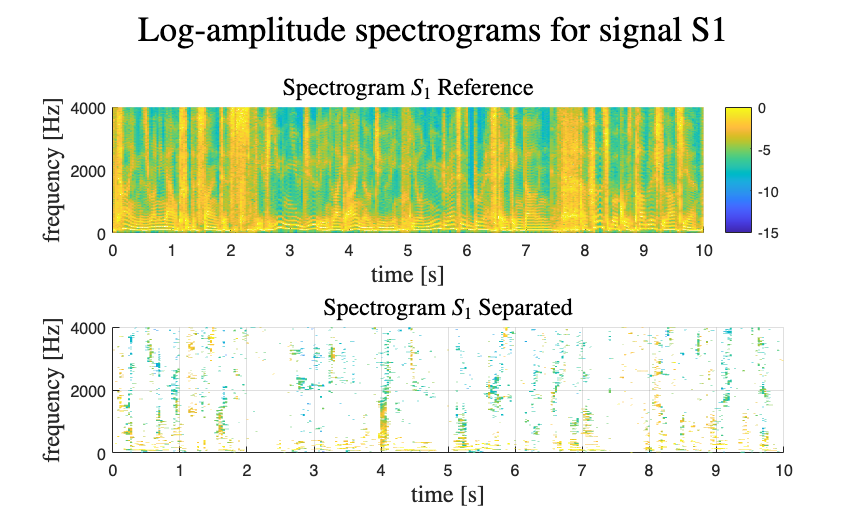

plotName = 'Log-amplitude spectrograms for the mixture signals';
%saveas(gcf,strcat("plots/",plotName),"png");
% FEATURES

%y_1_w_lin = reshape(y_1_st_w,size(y_1_st_w,1)*size(y_1_st_w,2),1);
%y_2_w_lin = reshape(y_2_st_w,size(y_2_st_w,1)*size(y_2_st_w,2),1);
y_11_w_lin = reshape(y_11_st_w,size(y_11_st_w,1)*size(y_11_st_w,2),1);
y_22_w_lin = reshape(y_22_st_w,size(y_22_st_w,1)*size(y_22_st_w,2),1);




if(length(y_22_w_lin) ~= length(y_11_w_lin))
    disp("error between microphones signal length")
end

FI = zeros(length(y_11_w_lin),3);

% compute first and feature
for ii = 1:length(y_11_w_lin)
   Y_11 = y_11_w_lin(ii);
   Y_22 = y_22_w_lin(ii);
   root_sum = (sqrt(abs(Y_11)^2 + abs(Y_22)^2));
   A_11 = abs(Y_11) / root_sum;
   A_22 = abs(Y_22) / root_sum;
   P = 1/(2*pi) * angle(Y_22/Y_11);
   
   %P_1 = 1/(2*pi) * angle(Y_2/Y_1);
   %P_2 = 1/(2*pi) * angle(Y_1/Y_2);
   FI(ii,1) = A_11;
   FI(ii,2) = A_22;
   FI(ii,3) = P;
   %FI(ii,3) = P_1;
   %FI(ii,4) = P_2;
end

[idx,C] = kmeans(FI,3);

%[idx,C] = kmeans(FI,3,"Distance","correlation","Start","cluster");


%density plot A_1 A_2
%figure 
%surf()


M_1_lin = zeros(length(idx),1);
M_2_lin = zeros(length(idx),1);
M_3_lin = zeros(length(idx),1);
for ii = 1: length(idx)
    if idx(ii) == 1
        M_1_lin(ii) = 1;
    elseif idx(ii) == 2
        M_2_lin(ii) = 1;
    elseif idx(ii) == 3
        M_3_lin(ii) = 1;
    end
end

M_1 = reshape(M_1_lin,size(y_11_st_w,1),size(y_11_st_w,2));
M_2 = reshape(M_2_lin,size(y_11_st_w,1),size(y_11_st_w,2));
M_3 = reshape(M_3_lin,size(y_11_st_w,1),size(y_11_st_w,2));







M_1_points = zeros(length(idx),2);
M_2_points = zeros(length(idx),2);
M_3_points = zeros(length(idx),2);
M_1_cur = 0;
M_2_cur = 0;
M_3_cur = 0;
% Masks plot 
for ii = 1:size(M_1,2)
    for jj = 1:size(M_1,1)
        if M_1(jj,ii) == 1
            M_1_points(M_1_cur+1,1) = jj;
            M_1_points(M_1_cur+1,2) = ii;
            M_1_cur = M_1_cur+1;
        elseif M_2(jj,ii) == 1
            M_2_points(M_2_cur+1,1) = jj;
            M_2_points(M_2_cur+1,2) = ii;
            M_2_cur = M_2_cur+1;
        elseif M_3(jj,ii) == 1
            M_3_points(M_3_cur+1,1) = jj;
            M_3_points(M_3_cur+1,2) = ii;
            M_3_cur = M_3_cur+1;
        end
    end
end

M_1_points = M_1_points(1:M_1_cur+1,:);
M_2_points = M_2_points(1:M_2_cur+1,:);
M_3_points = M_3_points(1:M_3_cur+1,:);




S_1_lin = y_11_w_lin .* M_1_lin;
S_2_lin = y_11_w_lin .* M_2_lin;
S_3_lin = y_11_w_lin .* M_3_lin;

S_1 = reshape(S_1_lin,size(y_11_st_w,1),size(y_11_st_w,2));
S_2 = reshape(S_2_lin,size(y_11_st_w,1),size(y_11_st_w,2));
S_3 = reshape(S_3_lin,size(y_11_st_w,1),size(y_11_st_w,2));

S_1_flip = conj(flip(S_1(2:end-1,:),1));
S_2_flip = conj(flip(S_2(2:end-1,:),1));
S_3_flip = conj(flip(S_3(2:end-1,:),1));




S_1 = [S_1;S_1_flip];
S_2 = [S_2;S_2_flip];
S_3 = [S_3;S_3_flip];



s_1_t = myistft(S_1,M,R);
s_2_t = myistft(S_2,M,R);
s_3_t = myistft(S_3,M,R);

% using crosscorrelation to match expected sources with results obtained by
% k-means

chosen_ref = zeros(1,3);
for i=1:3
    max_val_corr = 0;
    for j=1:3
        corr = abs(max(xcorr(eval(strcat("s_",num2str(i), "_t")),eval(strcat("s_",num2str(j), "_ref_t")))));
        if(corr>max_val_corr)
            chosen_ref(1,i) = j;
            max_val_corr=corr;
        end
    end
end



%legend("S_1","S_2","S_3")





% works but to be better implemented when the value 
% log-amplitude spectrograms of the true and estimated source signals (subplots).
% SIGNAL 1

% load and process reference 1
s_1_ref_st_w = mystft(s_1_ref_t,winType,M,R,0);
s_2_ref_st_w = mystft(s_2_ref_t,winType,M,R,0);
s_3_ref_st_w = mystft(s_3_ref_t,winType,M,R,0);

S_1_found = eval(strcat("S_",num2str(find(chosen_ref==1))));
S_2_found = eval(strcat("S_",num2str(find(chosen_ref==2))));
S_3_found = eval(strcat("S_",num2str(find(chosen_ref==3))));

% PLOTS

figure('Renderer', 'painters', 'Position', [10 10 1000 600])
%set(gcf,'position',[0,0,2000,2000])
%w1 = linspace(0,y_1_Fs/2,M/2);
%t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
S_11_ref = s_1_ref_st_w(1:M/2+1,:);
S_11 = S_1_found(1:M/2+1,:);
subplot(2,1,1)
surf(t,w1,log(abs(S_11_ref)./(max(abs(S_11_ref)))),EdgeColor="none");
colorbar
%surf(t,w1,db(abs(S_11)),EdgeColor="none");
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_1$  Reference',Interpreter='Latex', FontSize=axlabelsize);
%ylim([0 2000])
subplot(2,1,2)
surf(t,w1,log(abs(S_11)./(max(abs(S_11)))),EdgeColor="none");
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_1$ Separated',Interpreter='Latex', FontSize=axlabelsize);
sgtitle('Log-amplitude spectrograms for signal S1', FontSize=titlesize, Interpreter='Latex');

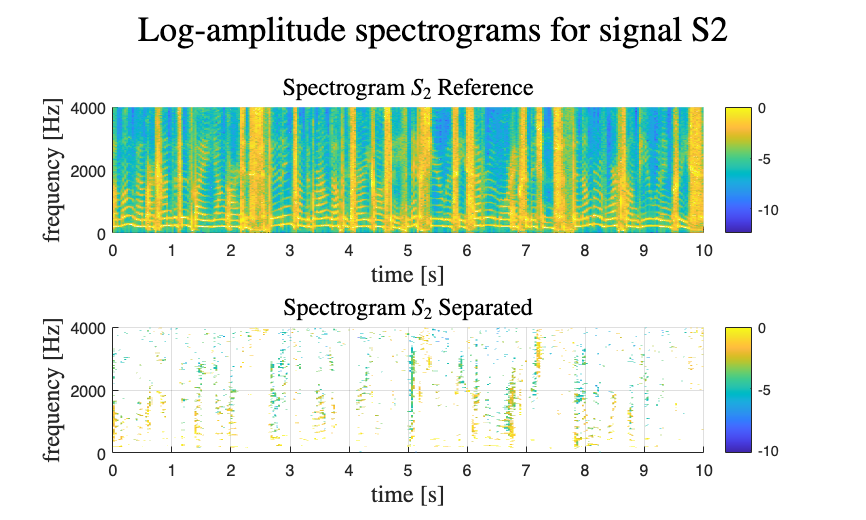

plotName = 'Log-amplitude spectrograms for signal S1';
%saveas(gcf,strcat("plots/",plotName),"png");

% Source 2
figure('Renderer', 'painters', 'Position', [10 10 1000 600]);
%set(gcf,'position',[0,0,2000,2000])
%w1 = linspace(0,y_1_Fs/2,M/2);
%t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
S_22_ref = s_2_ref_st_w(1:M/2+1,:);
S_22 = S_2_found(1:M/2+1,:);
subplot(2,1,1)
surf(t,w1,log(abs(S_22_ref)./(max(abs(S_22_ref)))),EdgeColor="none");
colorbar
%surf(t,w1,db(abs(S_11)),EdgeColor="none");
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_2$ Reference',Interpreter='Latex', FontSize=axlabelsize);
%ylim([0 2000])
subplot(2,1,2)
surf(t,w1,log(abs(S_22)./(max(abs(S_22)))),EdgeColor="none");
colorbar
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_2$ Separated',Interpreter='Latex', FontSize=axlabelsize);
sgtitle('Log-amplitude spectrograms for signal S2', FontSize=titlesize, Interpreter='Latex');

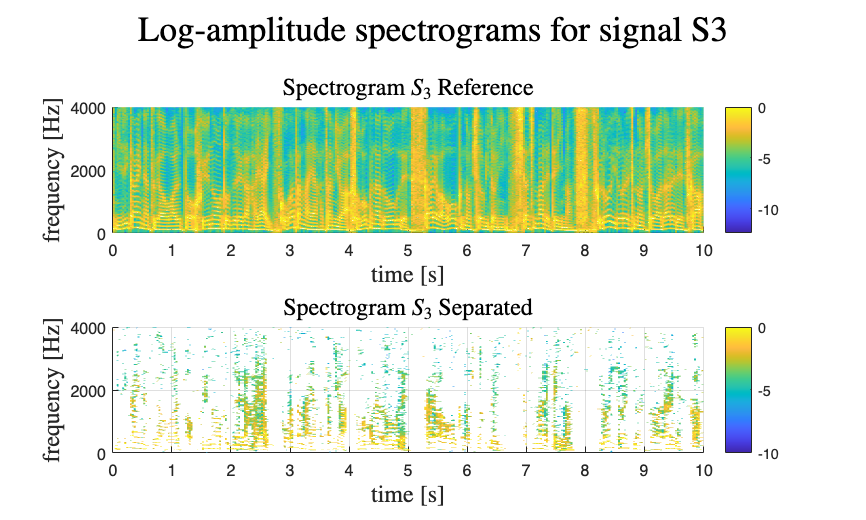

plotName = 'Log-amplitude spectrograms for signal S2';
%saveas(gcf,strcat("plots/",plotName),"png");

%Source 3
figure('Renderer', 'painters', 'Position', [10 10 1000 600]);
%set(gcf,'position',[0,0,2000,2000])
%w1 = linspace(0,y_1_Fs/2,M/2);
%t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
S_33_ref = s_3_ref_st_w(1:M/2+1,:);
S_33 = S_3_found(1:M/2+1,:);
subplot(2,1,1)
surf(t,w1,log(abs(S_33_ref)./(max(abs(S_33_ref)))),EdgeColor="none");
colorbar
%surf(t,w1,db(abs(S_11)),EdgeColor="none");
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_3$ Reference',Interpreter='Latex', FontSize=axlabelsize);
%ylim([0 2000])
subplot(2,1,2)
surf(t,w1,log(abs(S_33)./(max(abs(S_33)))),EdgeColor="none");
colorbar
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_3$ Separated',Interpreter='Latex', FontSize=axlabelsize);
sgtitle('Log-amplitude spectrograms for signal S3', FontSize=titlesize, Interpreter='Latex');

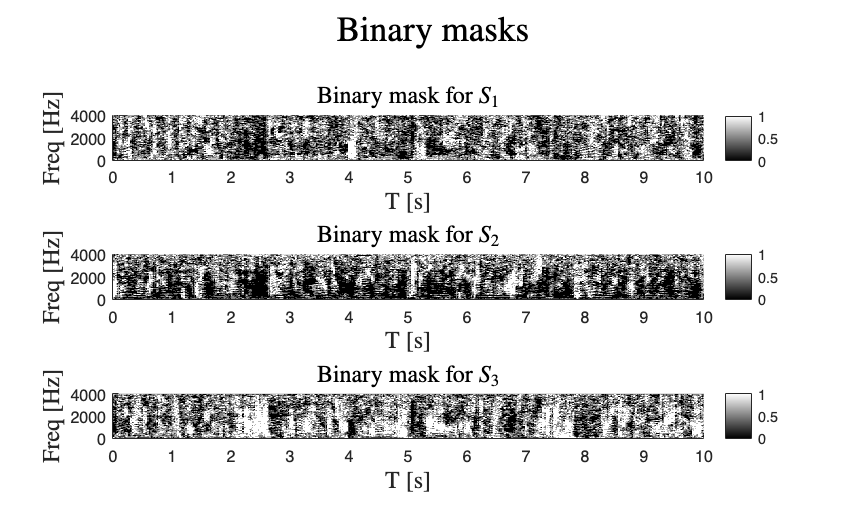

plotName = 'Log-amplitude spectrograms for signal S3';
%saveas(gcf,strcat("plots/",plotName),"png");


M_1_points_found = eval(strcat("M_",num2str(find(chosen_ref==1)),"_points"));
M_2_points_found = eval(strcat("M_",num2str(find(chosen_ref==2)),"_points"));
M_3_points_found = eval(strcat("M_",num2str(find(chosen_ref==3)),"_points"));

% figure
% set(gcf,'position',[0,0,2000,2000])
% subplot(3,1,1)
% s1 = pcolor(M_1);
% s1.LineWidth = 0.0001;
% c = gray(2);
% c = flipud(c);
% colormap(c);
% 
% subplot(3,1,2)
% s2 = pcolor(M_2);
% s2.LineWidth = 0.0001;
% c = gray(2);
% c = flipud(c);
% colormap(c);
% subplot(3,1,3)
% s3 = pcolor(M_2);
% s3.LineWidth = 0.0001;
% c = gray(2);
% c = flipud(c);
% colormap(c);

% binary masks subplot
figure('Renderer', 'painters', 'Position', [10 10 1000 600]);
%set(gcf,'position',[0,0,2000,2000])
subplot(3,1,1)
%scatter(M_1_points_found(:,2),M_1_points_found(:,1),3,'black','filled','square','LineWidth',2)
surf(t,w1,M_1,EdgeColor="none")
view(0,90);
colormap("gray")
colorbar;
subtitle('Binary mask for $S_1$',Interpreter='Latex', FontSize=axlabelsize);
%ylim([1 size(M_1,1)]);
%xlim([1 size(M_1,2)+1])
%xticks(1:size(M_1,2)/10:size(M_1,2))
%xticklabels(0:1:10)
xlabel("T [s]",Interpreter='Latex', FontSize=axlabelsize)
ylabel("Freq [Hz]",Interpreter='Latex', FontSize=axlabelsize)
subplot(3,1,2)

%scatter(M_2_points_found(:,2),M_2_points_found(:,1),3,'black','filled','square')
surf(t,w1,M_2,EdgeColor="none")
view(0,90);
colorbar;
colormap("gray")
subtitle('Binary mask for $S_2$',Interpreter='Latex', FontSize=axlabelsize);
%ylim([1 size(M_2,1)]);
%xlim([1 size(M_2,2)+1])
%xticks(1:size(M_1,2)/10:size(M_1,2))
%xticklabels(0:1:10)
xlabel("T [s]", Interpreter='Latex',FontSize=axlabelsize)
ylabel("Freq [Hz]", Interpreter='Latex',FontSize=axlabelsize)
subplot(3,1,3)

%scatter(M_3_points_found(:,2),M_3_points_found(:,1),3,'black','filled','square')
surf(t,w1,M_3,EdgeColor="none")
view(0,90);
colorbar;
colormap("gray")
subtitle('Binary mask for $S_3$',Interpreter='Latex', FontSize=axlabelsize);
%ylim([1 size(M_3,1)]);
%xlim([1 size(M_3,2)]+1);
%xticks(1:size(M_1,2)/10:size(M_1,2))
%xticklabels(0:1:10)
xlabel("T [s]",Interpreter='Latex',FontSize=axlabelsize)
ylabel("Freq [Hz]",Interpreter='Latex', FontSize=axlabelsize)
sgtitle('Binary masks', FontSize=titlesize, Interpreter='Latex');

plotName = 'Binary masks';
%saveas(gcf,strcat("plots/",plotName),"png");

% mask check
M_123 = M_1 + M_2 + M_3;
if(isempty(find(M_123~=1, 1)))
    disp("sum of masks is correct")
else 
    disp("error on mask check")
end

sum of masks is correct


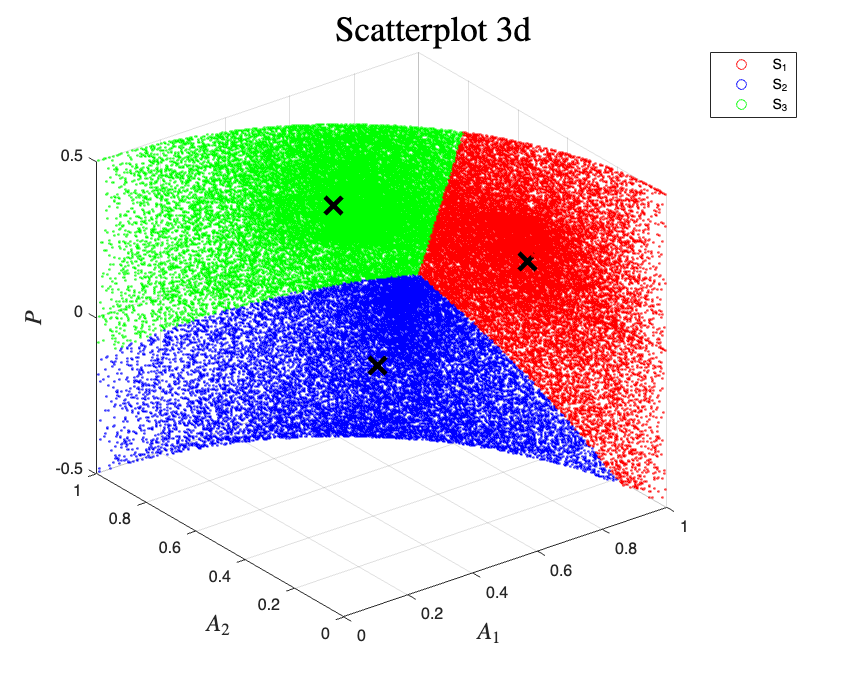



% scatterplot3d of the distribution in feature space
figure('Renderer', 'painters', 'Position', [10 10 1000 800]);
%set(gcf,'position',[0,0,2000,2000])
scatter3(FI(idx==1,1),FI(idx==1,2),FI(idx==1,3),1,'ro')
hold on
scatter3(FI(idx==2,1),FI(idx==2,2),FI(idx==2,3),1,'bo')
hold on
scatter3(FI(idx==3,1),FI(idx==3,2),FI(idx==3,3),1,'go')
hold on 
plot3(C(:,1),C(:,2),C(:,3),'kx',...
     'MarkerSize',15,'LineWidth',3) 
xlabel("$A_1$" ,Interpreter='Latex', FontSize=axlabelsize)
ylabel("$A_2$",Interpreter='Latex', FontSize=axlabelsize)
zlabel("$P$",Interpreter='Latex', FontSize=axlabelsize)
labels = [strcat("S_",num2str(chosen_ref(1))),strcat("S_",num2str(chosen_ref(2))),strcat("S_",num2str(chosen_ref(3)))];
legend(labels);
sgtitle('Scatterplot 3d', FontSize=titlesize, Interpreter='Latex');

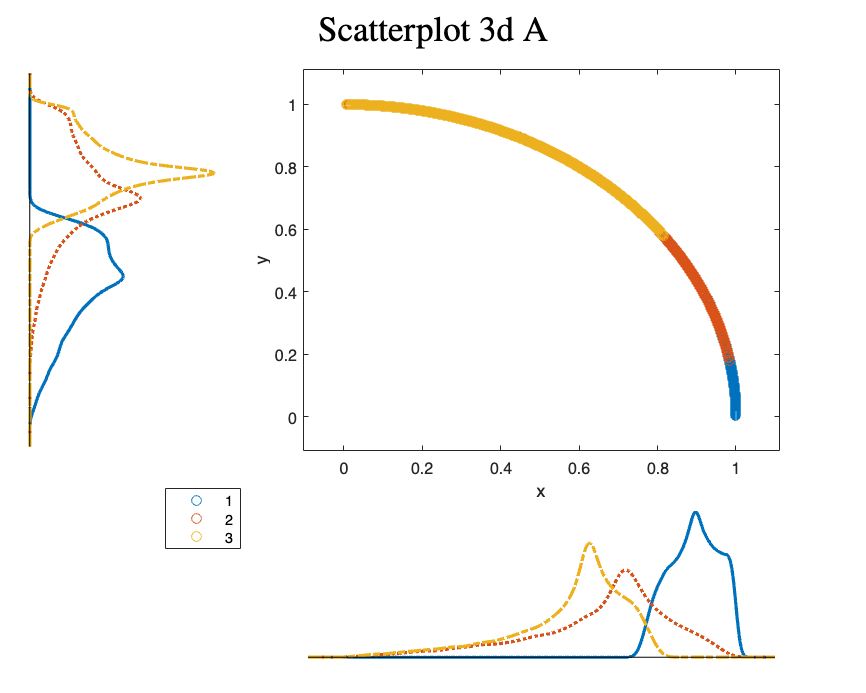

plotName = 'Scatterplot 3d';
%saveas(gcf,strcat("plots/",plotName),"png");

% scatterplot histogram A_1 A_2 
figure('Renderer', 'painters', 'Position', [10 10 1000 800]);
scatterhist(FI(:,1),FI(:,2),"Group",idx,"Kernel","on")
sgtitle('Scatterplot 3d A', FontSize=titlesize, Interpreter='Latex');

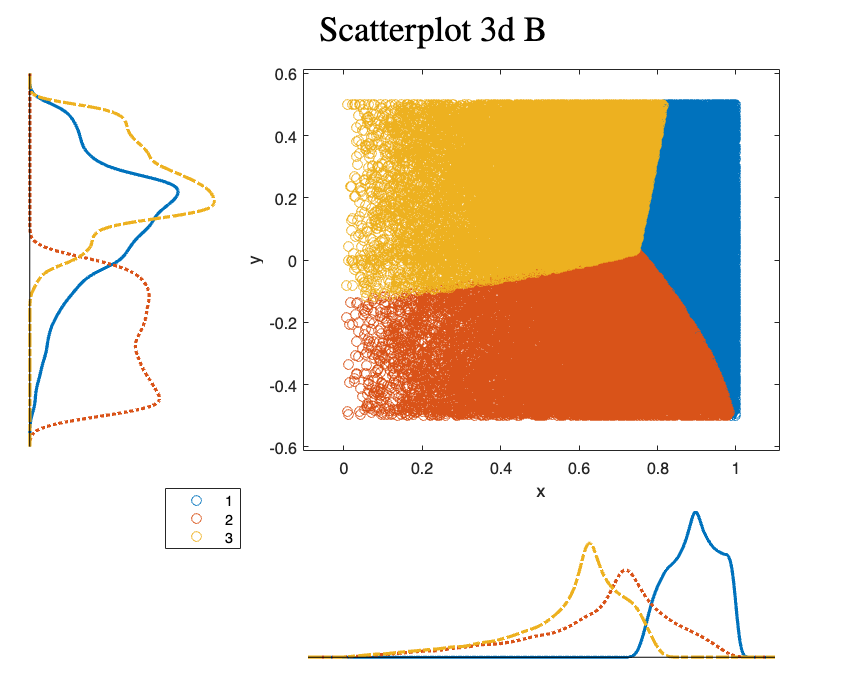

plotName = 'Scatterplot 3d A';
%saveas(gcf,strcat("plots/",plotName),"png");


figure('Renderer', 'painters', 'Position', [10 10 1000 800]); 
scatterhist(FI(:,1),FI(:,3),"Group",idx,"Kernel","on")
sgtitle('Scatterplot 3d B', FontSize=titlesize, Interpreter='Latex');

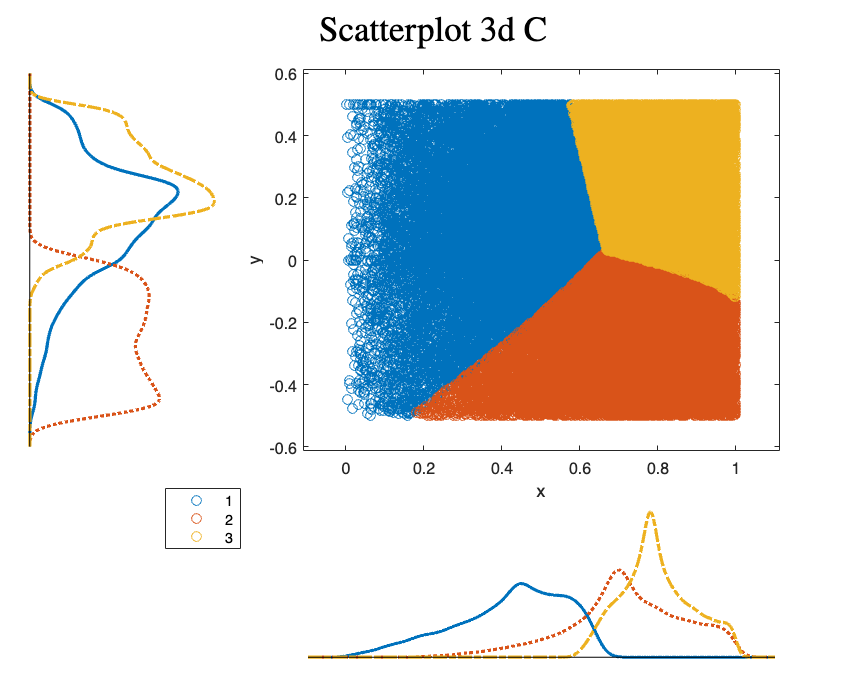

plotName = 'Scatterplot 3d B';
%saveas(gcf,strcat("plots/",plotName),"png");


figure('Renderer', 'painters', 'Position', [10 10 1000 800]);
scatterhist(FI(:,2),FI(:,3),"Group",idx,"Kernel","on")
sgtitle('Scatterplot 3d C', FontSize=titlesize, Interpreter='Latex');

plotName = 'Scatterplot 3d C';
%saveas(gcf,strcat("plots/",plotName),"png");
%scatterhist(FI(:,2),FI(:,3),"Kernel","on")


%for nn = 1:size(S_1,2)
%    S_1(M+1:2*M+1,nn) = 0;
%    S_2(M+1:2*M+1,nn) = 0;
%    S_3(M+1:2*M+1,nn) = 0;
%end


s_1_t_found = eval(strcat("s_",num2str(find(chosen_ref==1)),"_t"));
s_2_t_found = eval(strcat("s_",num2str(find(chosen_ref==2)),"_t"));
s_3_t_found = eval(strcat("s_",num2str(find(chosen_ref==3)),"_t"));


% 
% audiowrite("./audioOutputs/"+s_1_name,real(s_1_t)/max(real(s_1_t)),y_1_Fs);
% audiowrite("./audioOutputs/"+s_2_name,real(s_2_t)/max(real(s_2_t)),y_1_Fs);
% audiowrite("./audioOutputs/"+s_3_name,real(s_3_t)/max(real(s_3_t)),y_1_Fs);


audiowrite("./audioOutputs/"+s_1_name,real(s_1_t_found),y_1_Fs);
audiowrite("./audioOutputs/"+s_2_name,real(s_2_t_found),y_1_Fs);
audiowrite("./audioOutputs/"+s_3_name,real(s_3_t_found),y_1_Fs);